# Simulating phase measurement 

## Objective

Explore data recovery from noise, and measuring amplitude and phase in the frequency domain. 

### Recovering amplitudes and phases from time series data

1. Simulate  data using the model A = sin(2*pi*F*t+P) + noise

t = [1:1000]'; % e.g. 1 second clock at 1 kHz sample rate
a = sin(2 * pi * t / 100); % pure signal
b = 1.1 * sin(2*pi*t/100+2); % different amplitude and phase

If all we had was data a and b, how would we extract the amplitude and phase? 

The standard way to get the amplitude is mrms, I wrote this function: 

%{
function y = mrms(x)
% returns the rms mean with the dc component removed of a
% vector or each col of a matrix.  Also see rms().

y = sqrt(mean(x .* x) - mean(x) .^ 2);
%}
mrms([a b])

ans =     0.7071    0.7778


To get amplitudes from `mrms`, multiply by `sqrt(2)`: 

mrms([a b]) * sqrt(2)

ans =     1.0000    1.1000


There's another way, using the Fourier transform, that will give both amplitude and phase

fd = fft([a b]); % the first frequency is 0Hz, so 10 periods is the 11th frequency
fprintf('amplitudes = %f and %f \n', abs(fd(11,:)) * 2/length(a));

amplitudes = 1.000000 and 1.100000 


fprintf('phase difference = %f\n', diff(angle(fd(11,:))));

phase difference = 2.000000


Complex number magic! I want to now show you how robust this is to two types of perturbations. First, lets add some noise: 

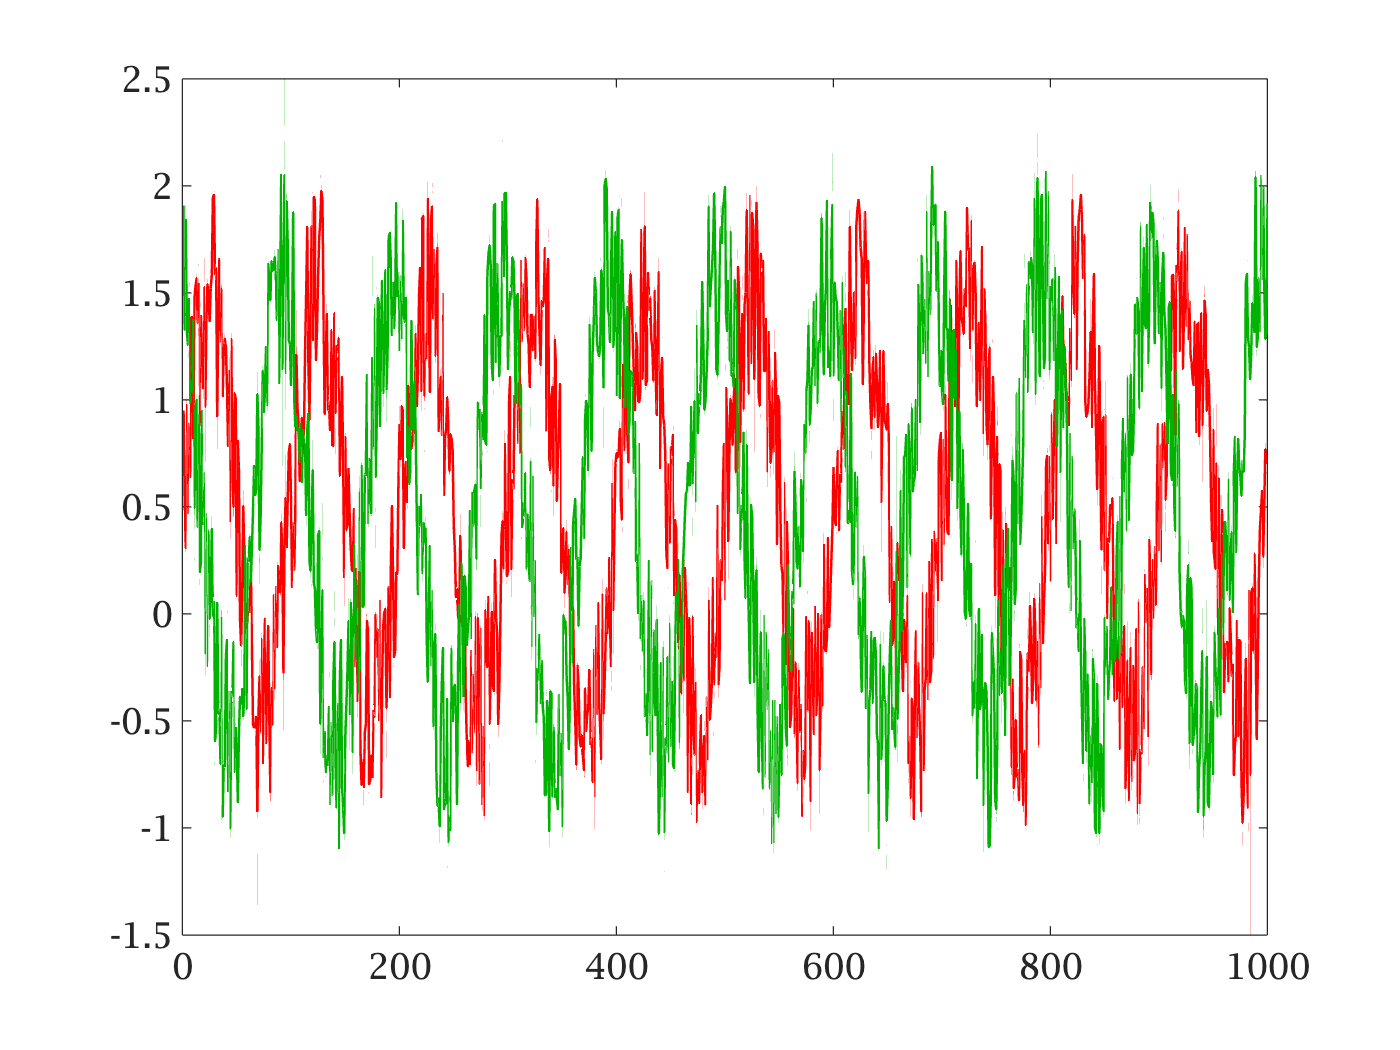

c = [a b]; 
c = c + rand(size(c)); % adding a unit of random noise
plot(c)

fc = fft(c); 
fprintf('rms amplitudes = %f and %f\n',mrms(c)*sqrt(2));

rms amplitudes = 1.076546 and 1.173123


fprintf('amplitudes = %f and %f \n', abs(fc(11,:)) * 2/length(a));

amplitudes = 0.995360 and 1.097821 


fprintf('phase difference = %f\n', diff(angle(fc(11,:))));

phase difference = 2.024469


One unit of noise adds about 10% to the rms ampltidue but less than 1% (!!) to the Fourier amplitudes. The Fourier phase is also off by <1%. That seems impressive ... let's verify with even more noise: 

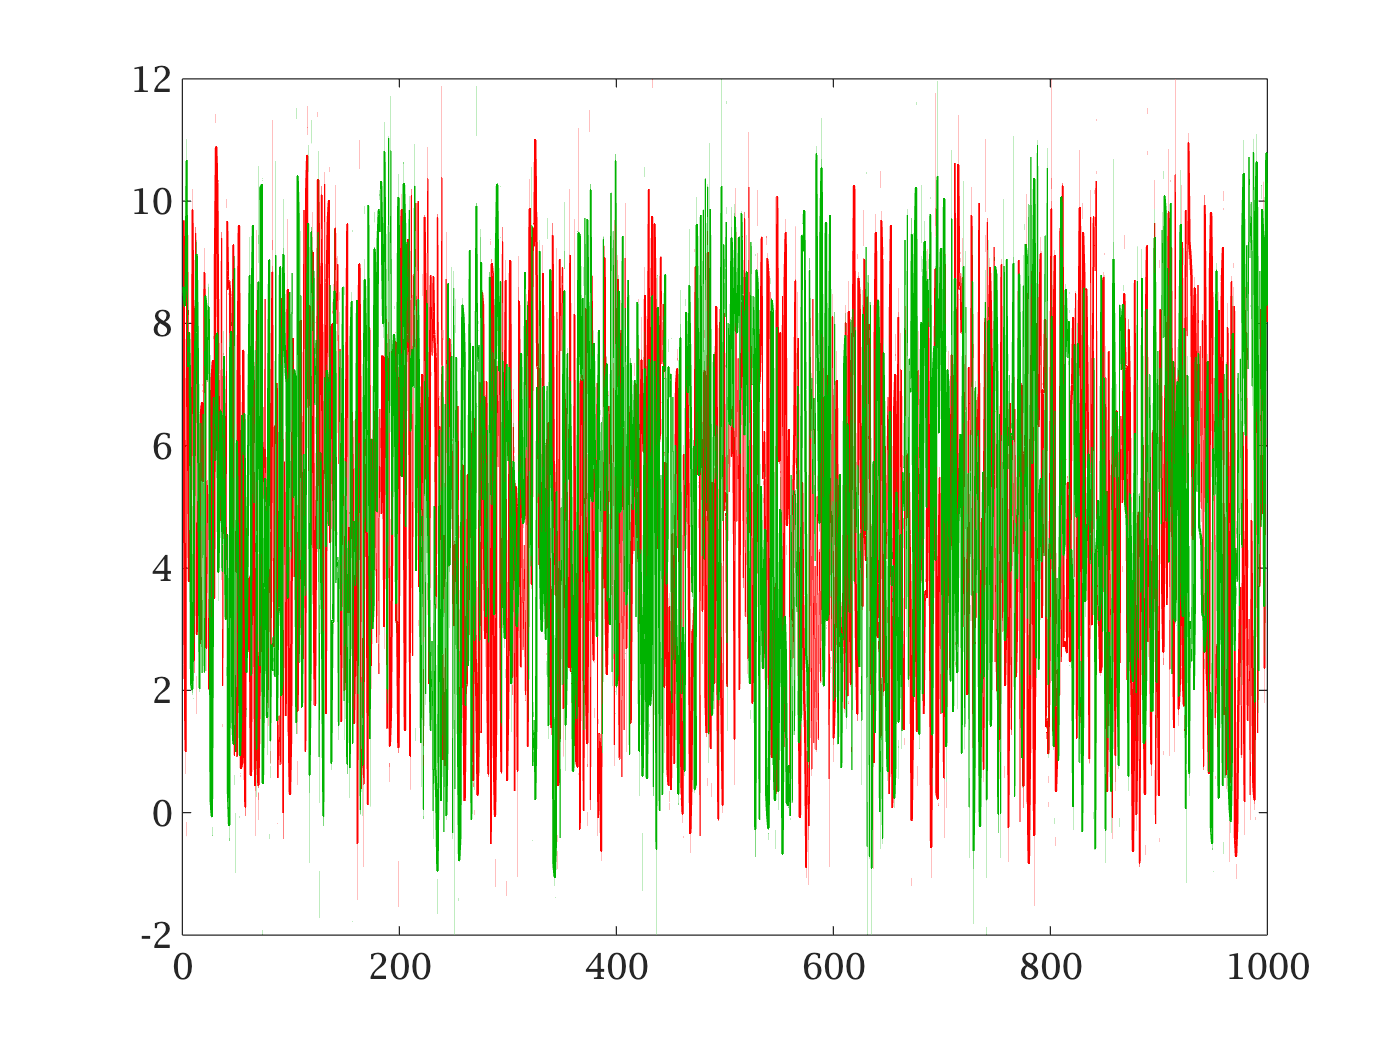

d = [a b];
d = d + 10* rand(size(d)); % adding random noise
plot(d)

fd = fft(d); 
fprintf('rms amplitudes = %f and %f\n',mrms(d)*sqrt(2));

rms amplitudes = 4.208971 and 4.239039


fprintf('amplitudes = %f and %f \n', abs(fd(11,:)) * 2/length(a));

amplitudes = 1.112109 and 1.239107 


fprintf('phase difference = %f\n', diff(angle(fd(11,:))));

phase difference = 2.033595


The noise dominates the rms signal -- looking at the plot, its not evident there is a signal in that noise. But the fft got the amplitude within ~10% and the phase within ~15%. So Fourier methods are super-robust to noise. Why? One way to think about this is that the signal (the sine wave) is spread out across time, and so is this noise. But in the "frequency domain", the signal is "localized" at just one frequency, whereas the noise is spread out over all frequencies. So by looking at just one one frequency where the signal is, we can ignore most of the noise. This may make more sense when seen graphically in the frequency domain. I wrote a function to do this called aspectrum: 

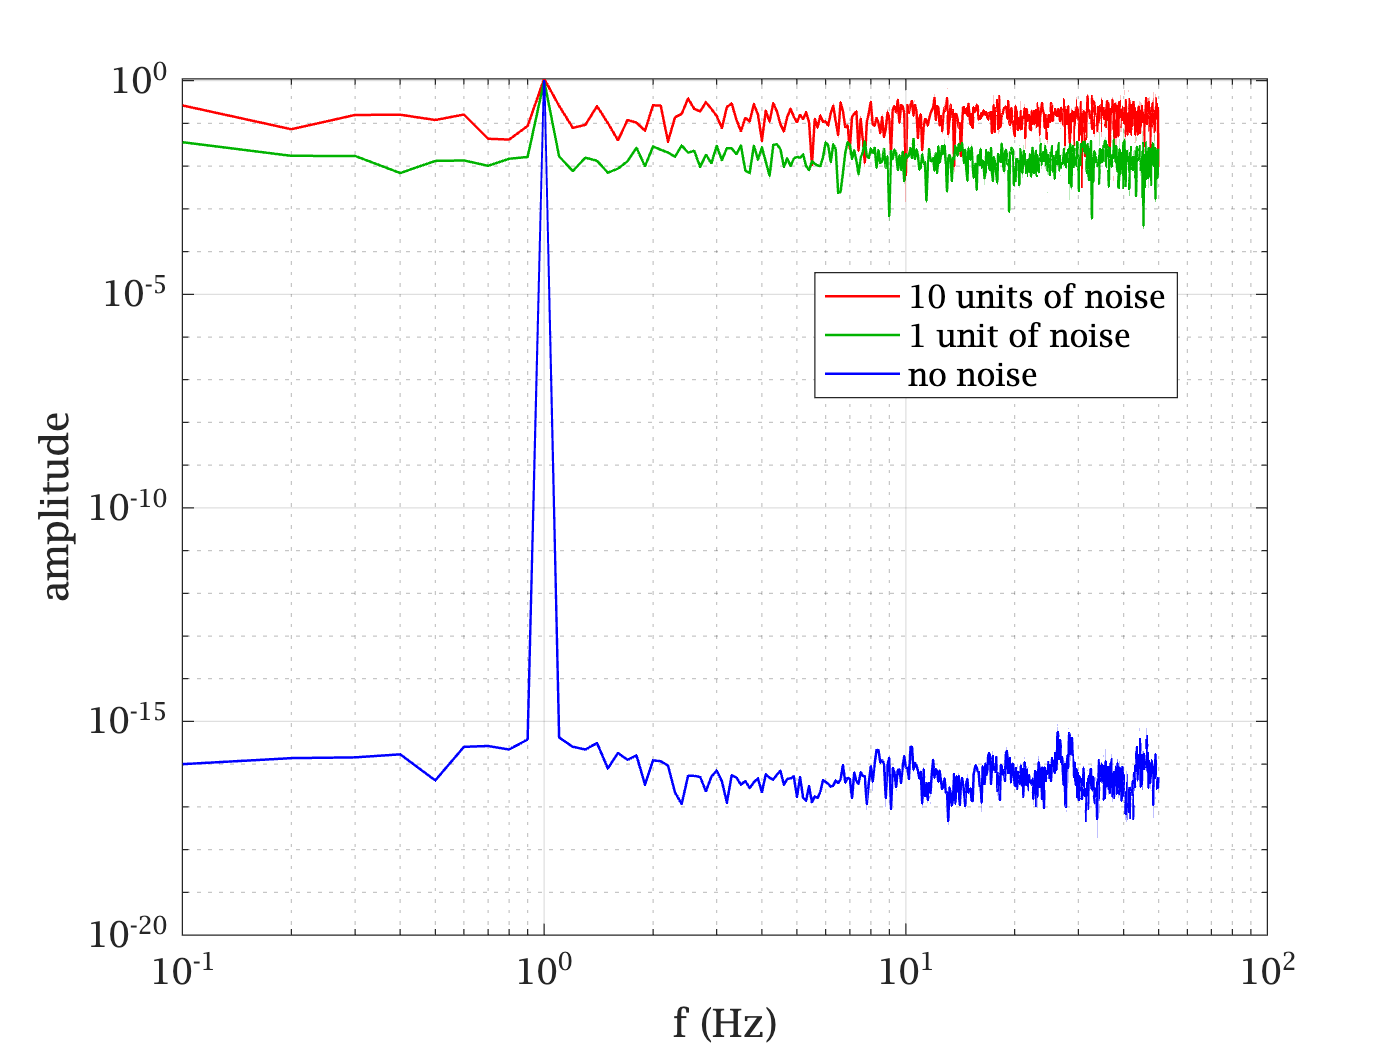

%{
function [d, x, phase] = aspectrum(v,rate)
% function [s, f, phase] = aspectrum(v,samplerate)
% compute amplitude spectrum of vector v or matrix v of
% column vectors. col vectors of d are spectral components.
% the second argument (optional) is the sample rate (Hz)
% and will plot the spectrum.  Phase in degrees.
% f is the frequency axis of the spectrum plot.

% 3-12-92, B.R. deleted dc component from result.
% 13 Oct 93, B.R. return phase

len = length(v(:,1));
if len == 1, v = v'; len = length(v(:,1)); end
fb = fft(v);
d = 2 * abs(fb) / len;
if nargin == 2
  n = floor(len / 2); % added floor 8may19 BR
  x = 1:n-1;  x = x' * rate / len; 
  d = d(2:n,:);  % drop DC
  loglog(x,d)
  xlabel('f (Hz)'); ylabel('amplitude');
  grid;
  if nargout == 3
    phase = angle(fb(2:n,:)) * 180 / pi;
  end
end

return;

%% for dc use:
  x = 0:n-1;  x = x' * rate / 2 / n; 
  d = d(1:n,:);  % added 1-16-92
%}
aspectrum([d(:,1) c(:,1) a],100); 
legend('10 units of noise','1 unit of noise','no noise','location','best')

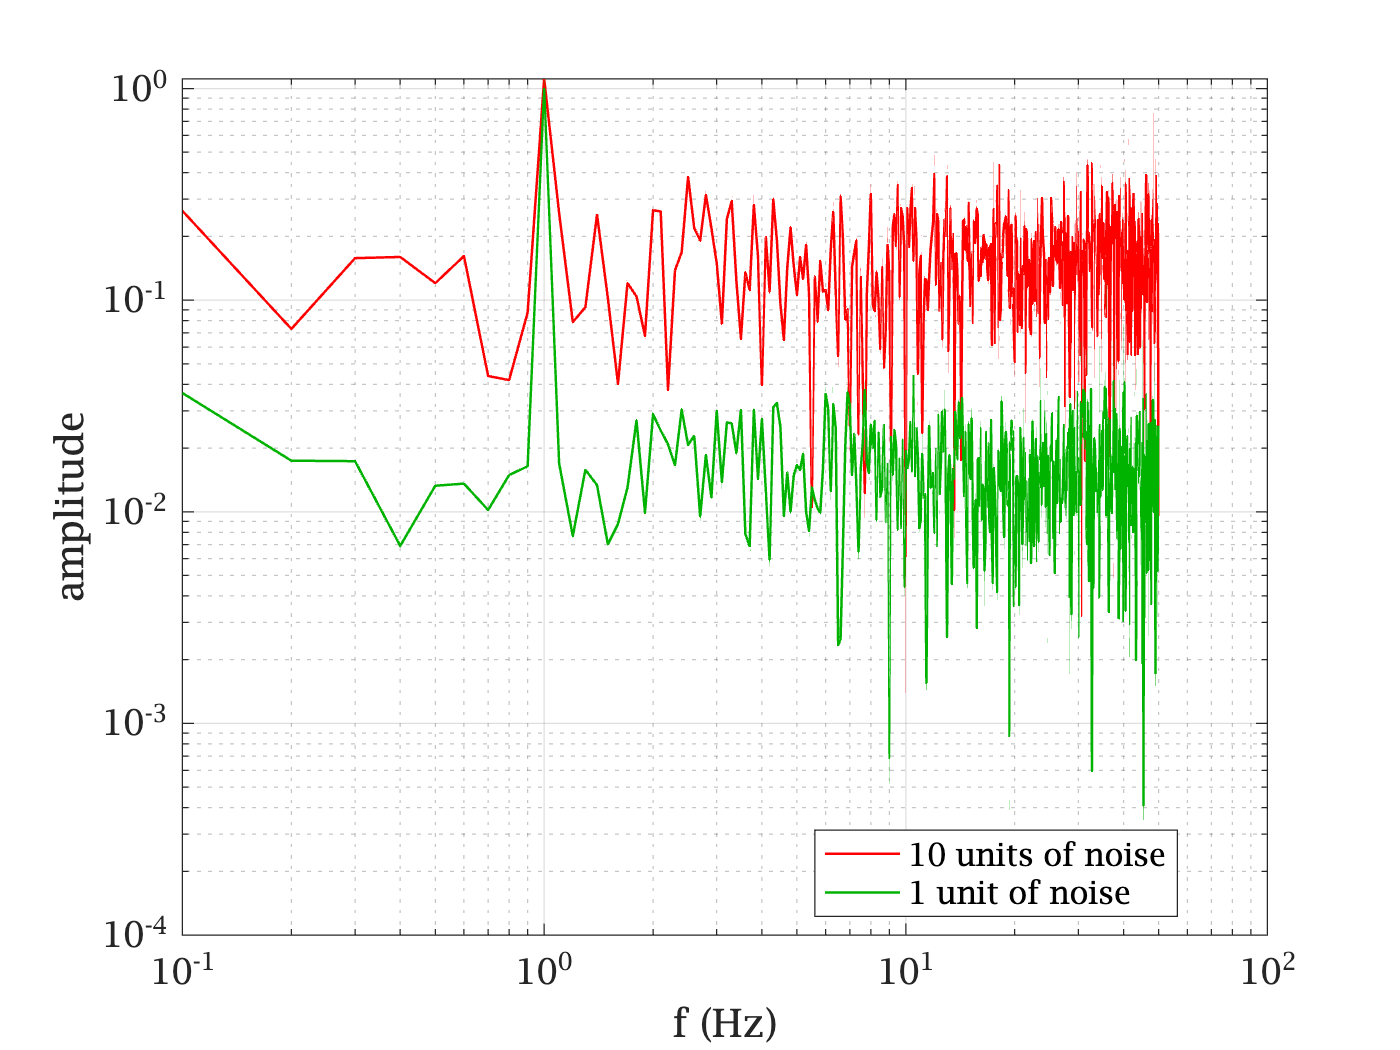

figure; 
aspectrum([d(:,1) c(:,1)],100); 
legend('10 units of noise','1 unit of noise','location','best')

We see how the "noise floor" is different for these 3 sets of data. Without added noise, the "floor" is 1e-16, from rounding errors in floating point numbers. Adding 1 unit of noise raised the "floor" to ~.02, and  10 units of noise raised it to ~.2. 

### Effects of sample size 

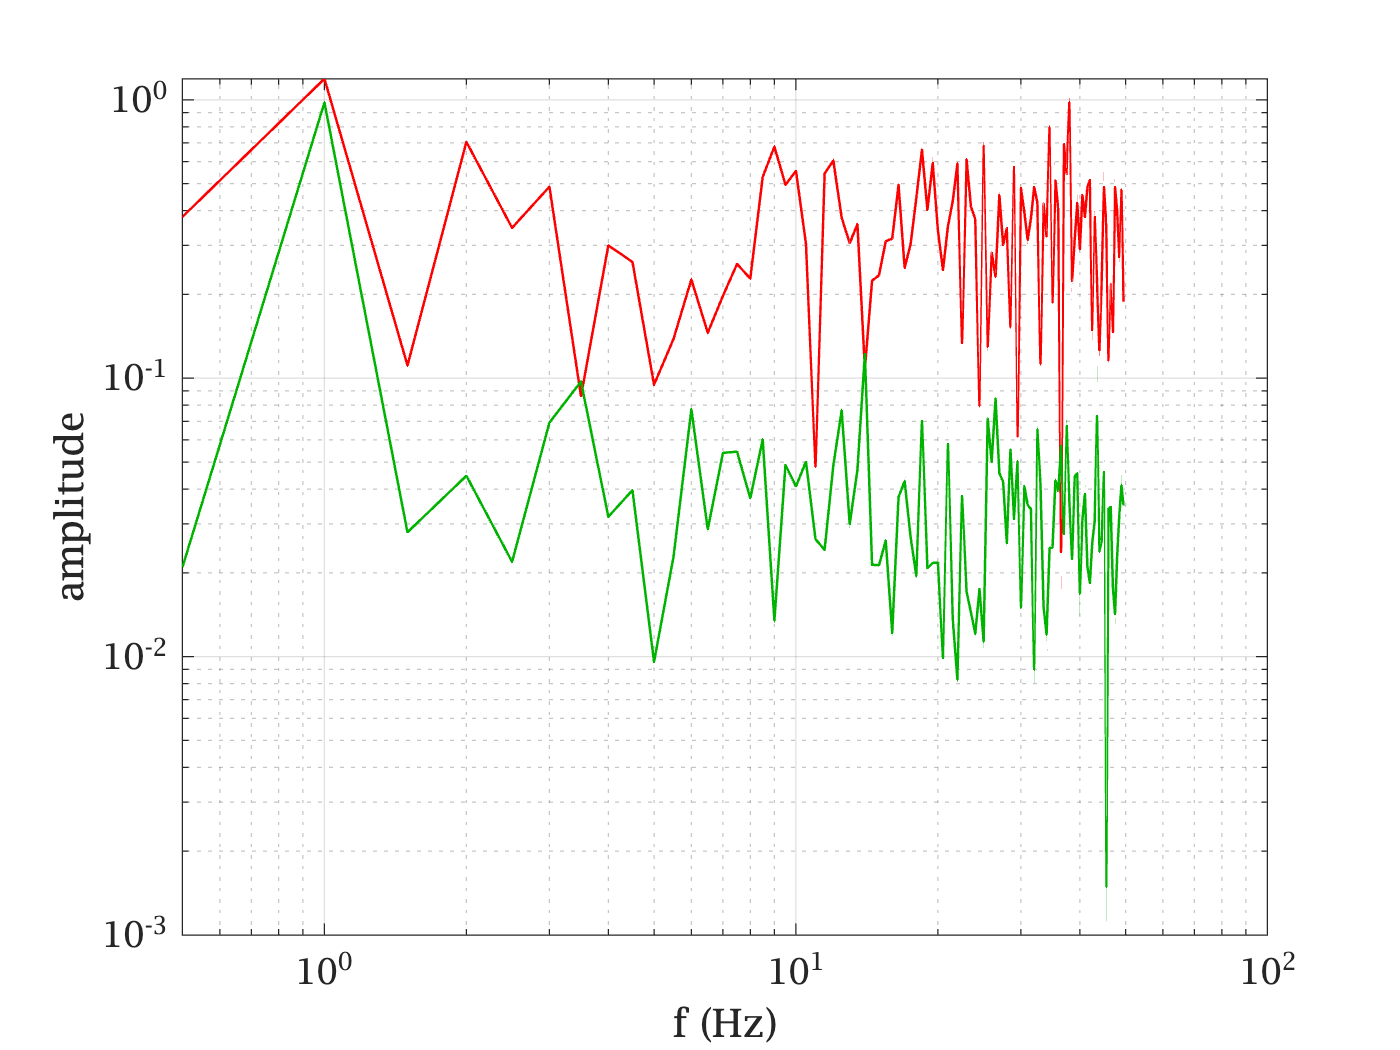

aspectrum([d(1:200,1) c(1:200,1)],100);

That clearly raises the noise floors (not clear if by 5x or less). You can also explore 1/2 the data, etc. 

Let's explore more systematically how the number of data points or the sample size affects noise.  Let's start again with a without noise: 

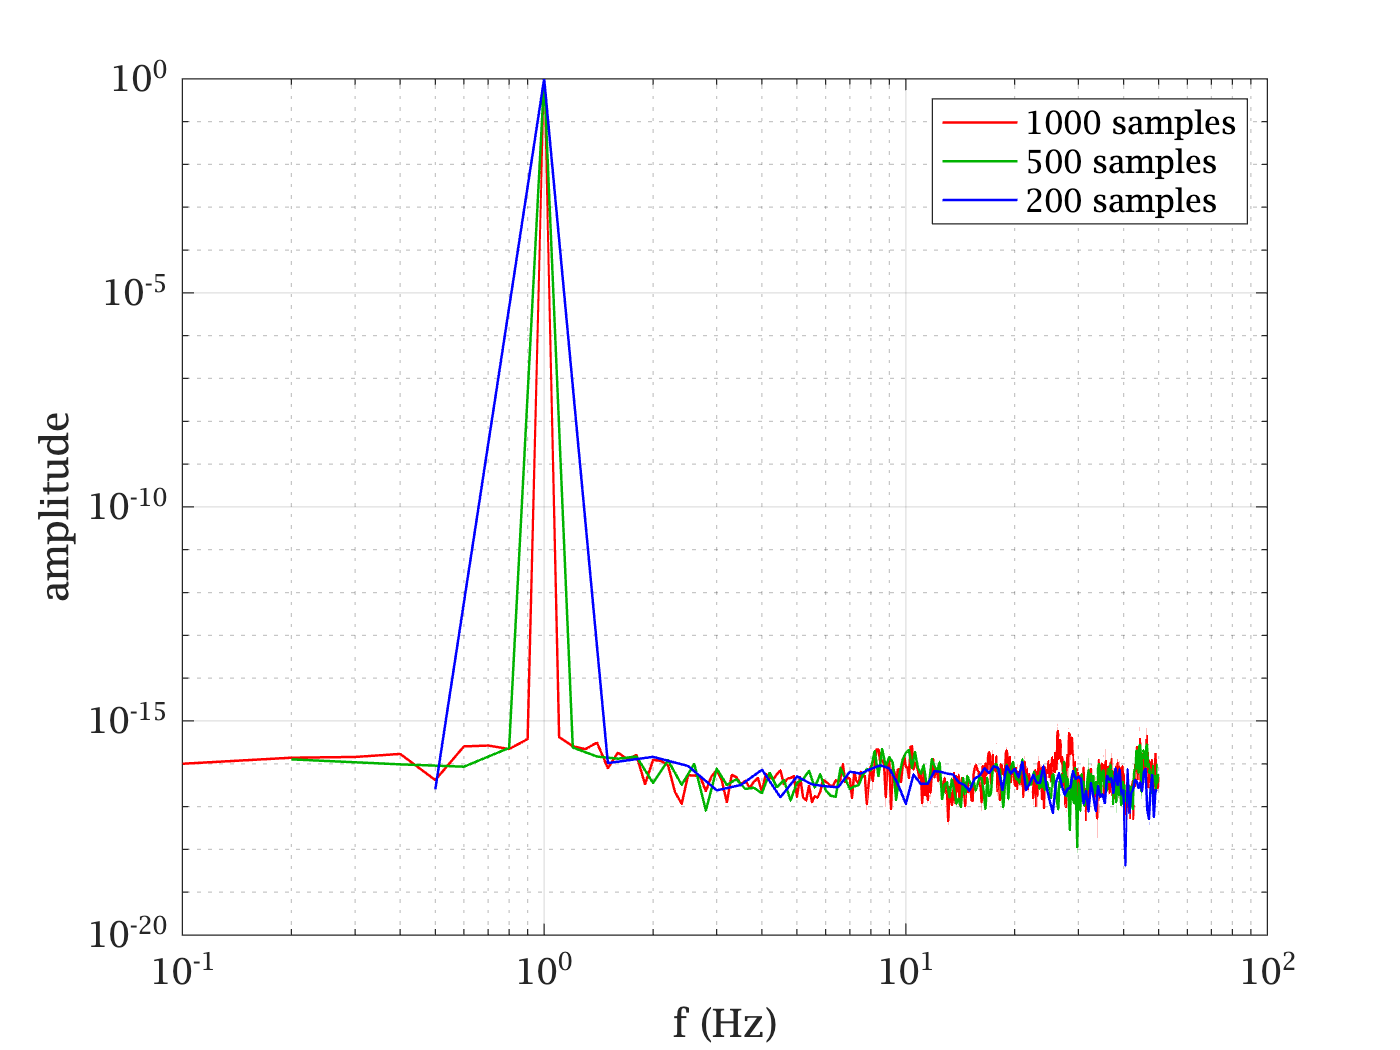

[s1 f1] = aspectrum(a,100); hold on; 
[s2 f2] = aspectrum(a(1:500),100);
[s3 f3] = aspectrum(a(1:200),100);
legend('1000 samples','500 samples', ...
    '200 samples')
hold off;

The fewer samples in the time domain, the wider the frequency "bins" or "bands" in the frequency domain. More time points affords better frequency resolution (and maybe lower noise per bin? Not evident with "round-off noise"). 

### Tiny changes in sample size have *huge* effects

What if we delete just one data point (instead of 1/2 or 4/5 of them). Changing the lenght of the data by 

100/(length(a)-1)

ans = 0.1001

percent shouldn't make a lot of difference, should it? 

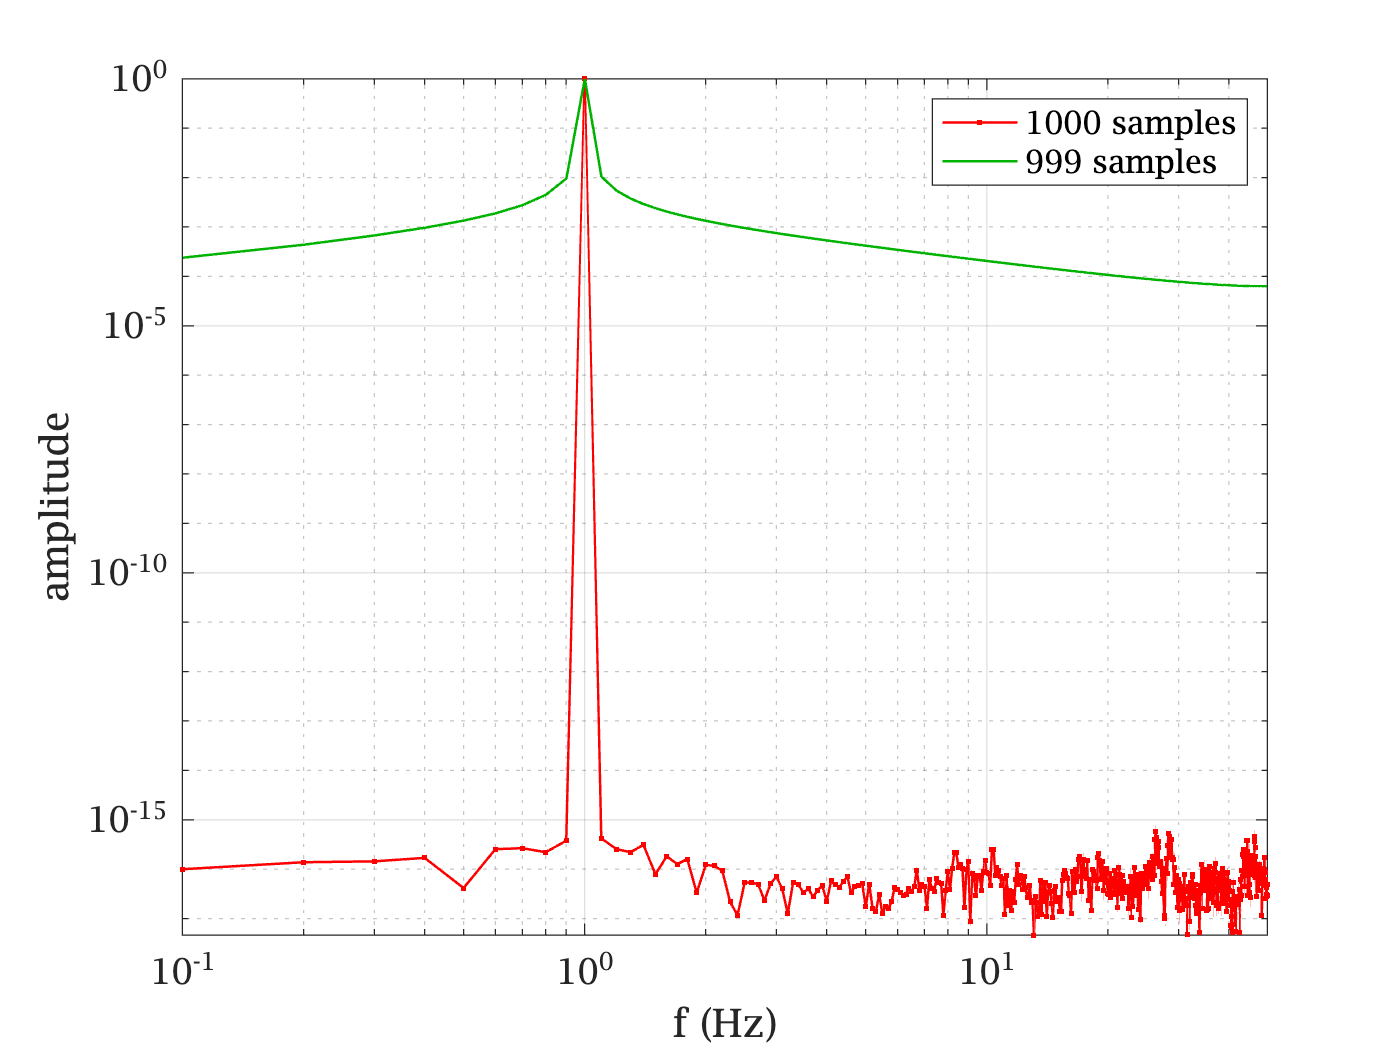

aspectrum(a,100); dots; 
hold on;
aspectrum(a(2:end),100); grid
legend(sprintf('%d samples',length(a)), ...
        sprintf('%d samples', length(a)-1));
hold off; axis tight

What the heck happened??? Tossing 1 sample point destroyed 10 logs (ten billion!) of signal-to-noise ratio!! And it devastated the Q-factor (narrowness) of the peak as well! How to explain this? 

The Fourier transform assumes the data is periodic. Assume is the wrong word, it makes it so. It forces data(end+1) = data(1), so if those aren't the same, if there's a discontinuity between the first and last sample, then that "step function" gets Fourier transformed into all frequencies. The Fourier transform of a step or delta function is a continuoum spectrum (all frequencies), conversely the Fourier transform of a sine (all times) is a delta function (one frequency). The temporally discrete artifact of a discontinuity between the first and last data points transforms into energy artifacts spread across all frequencies. This hypersensitivity to discontinuities is called "ill conditioned" by mathematicians. And its the opposite of what you usually want a signal processing algorithm to do.

The Fourier transform is most useful when the signal of interest is harmonic or made up of a few discrete frequencies or a narrow band, and the noise is spread into other frequencies or bands. Thus in Fourier space, a periodic signal of interest essentially gets concentrated, localized, while the (non-periodic) noise remains spread out. Periodic noise also gets concentrated -- hopefully at frequencies you don't care about. Zeroing out the noise while focusing on the frequencies or bands of signal becomes feasible. But whenever you filter, always look at what the filter is filtering. Subtract raw signal from filtered signal and see if the difference is what you would call noise. A poorly designed filter can take out more signal, or it can create or add noise that wasn't there before -- like the high noise floor we got from removing 1 point from the data above. 

When using the Fourier transform, either 1) ensure you have exactly an integral number of periods, or 2) if you don't know the period or have multiple anharmonic periods, then you might "window" the data. Multiply it by a function before transforming it that minimizes the edge artifacts. There are several windowing function that trade off distortions, e.g., [Note: these require signal processing or DSP toolbox so I've commented them out]

%{
plot(window(@bartlett,1000))
hold on; 
plot(window(@blackman,1000))
plot(window(@chebwin,1000))
plot(window(@gausswin,1000))
hold off;
%}

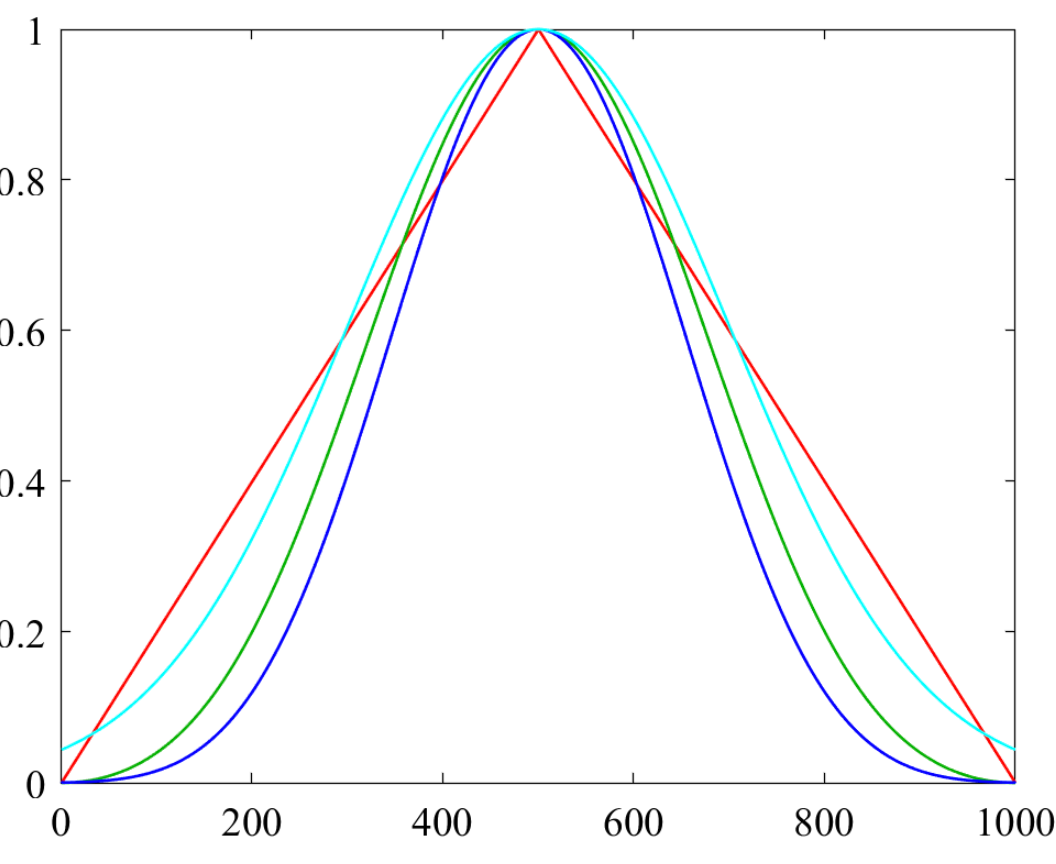

Some common window functions

% aspectrum([a(1:999) a(1:999) .* window(@hanning,999)],100);
% legend('999 pts','999 windowed'); dots

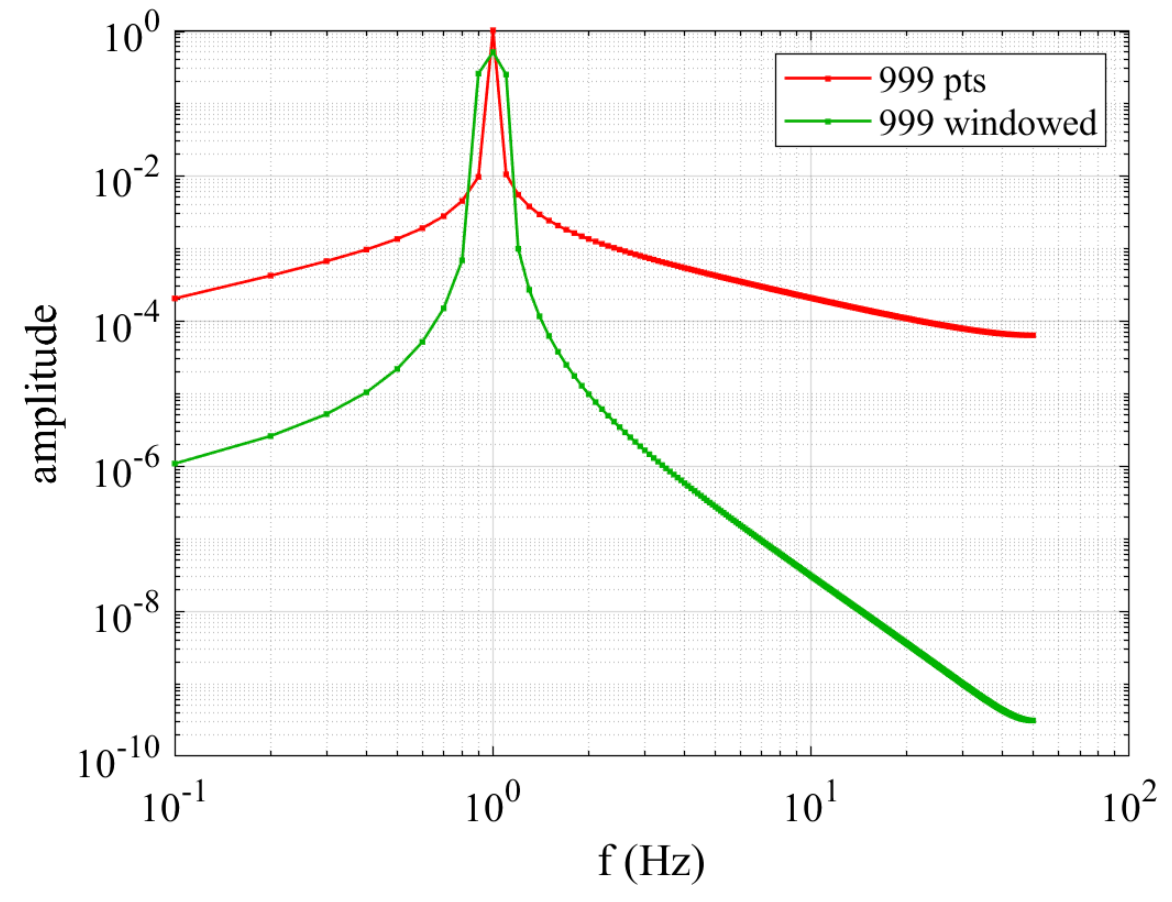

The Hanning window convolution spread out the energy peak into multiple frequency "bins" but attenuates the side lobes by a couple of logs ... Window functions can change amplitudes and phases, so you have to calibrate them ... That's a practical lesson in "ill conditioning" of the Fourier Transform. 

### Lock-in amplifiers

One more example of the power of Fourier methods. Imagine you have a photodetector that's measured the light from a pulsar, oscillating at 100Hz, and you measure at 10000 samples/sec for 10 seconds with a signal/noise ratio of 1/100, i.e., the random noise is 100 times greater than the signal. Can you detect the signal? Simulating data, we know what the signal looks like, the question is can the red curve below be found within the green data?

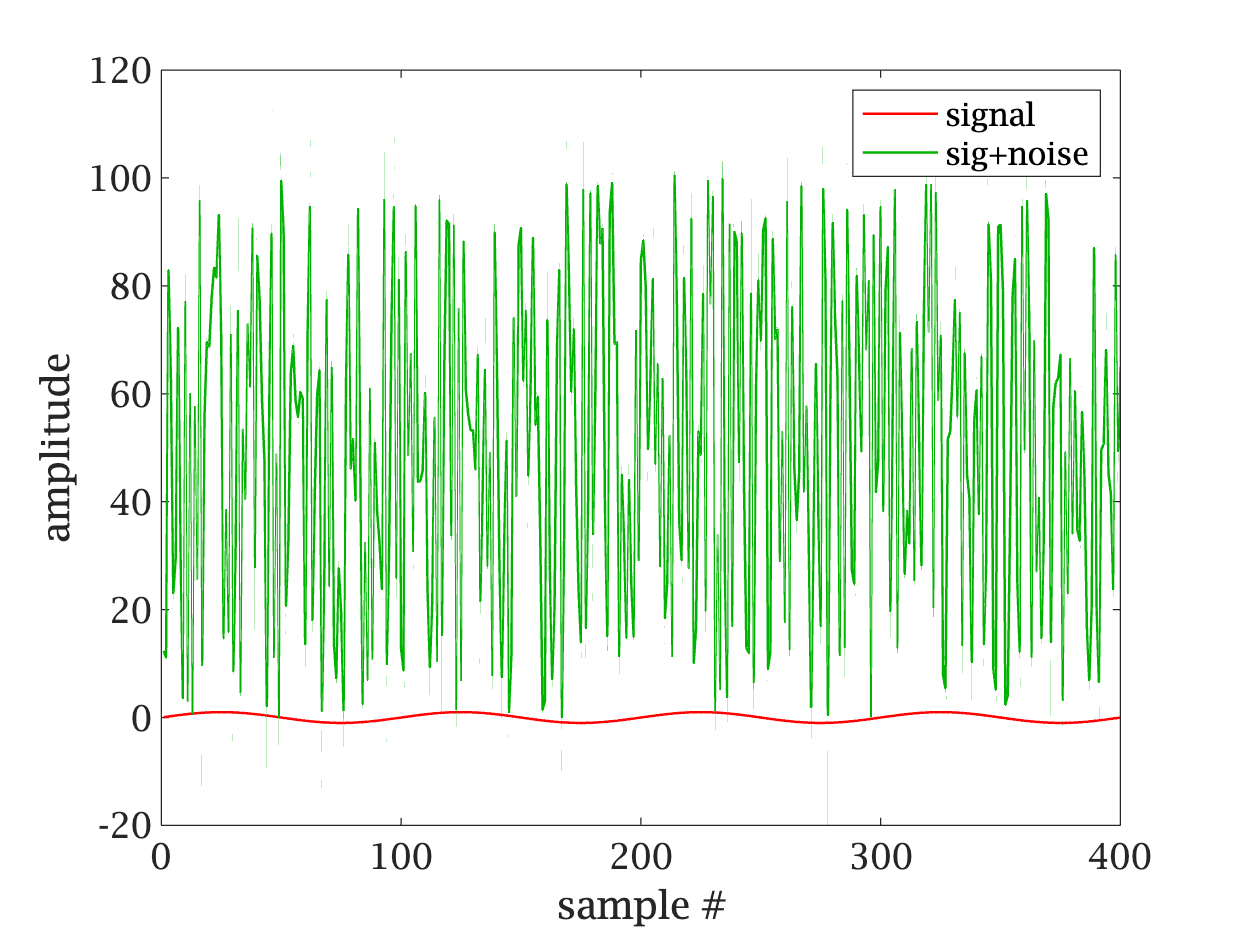

t = 1:1e5; t=t';
a = sin(2 * pi * t / 100); % signal
b = 100* rand(size(a)) + a; % 100 * more noise 
plot([a(1:400) b(1:400)]); xlabel('sample #'); ylabel('amplitude')
legend('signal','sig+noise')

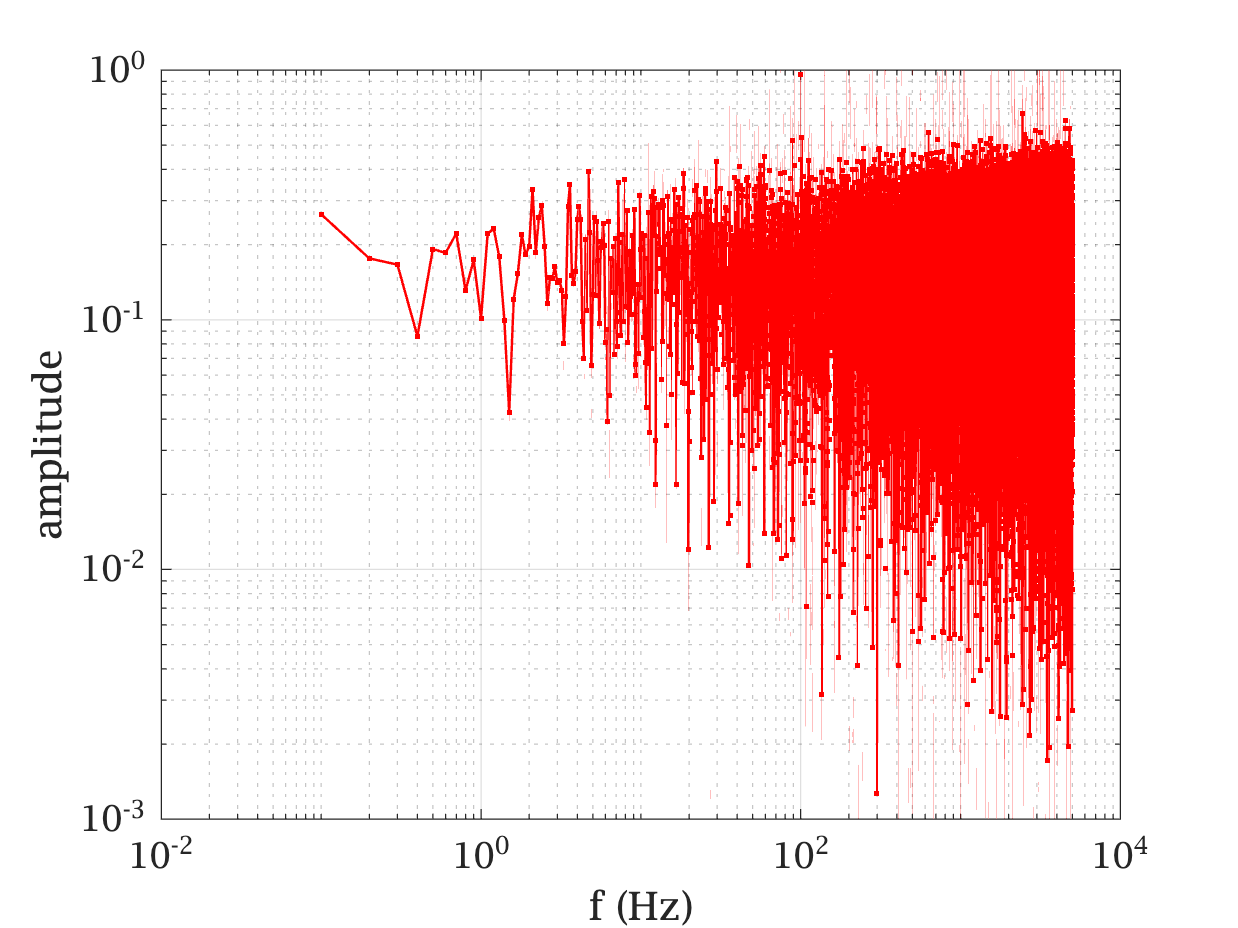

[ss ff] = aspectrum(b,1e4); 
dots

The signal at 100 Hz stands above the rest, and zooming in or querying the data, the amplitude is: 

ss(ff==100)

ans = 0.7360

Not a bad estimate for a signal-to-noise ratio of 1/100. Astronomers actually built a piece of hardware called a "lock-in amplifier" to look for pulsars this way, before computers were so fast and capable of doing this. The lock-in amplifier takes a signal (contaminated with noise) and typically a sine wave (or other periodic waveform) as a second input, it multiplies the two together (using analog multipliers), integrates and filters the resulting voltage, and displays it. Think of it like this, recall vector `a` is a sine wave that we're trying to find in the data, **b**. Let's make a control variable that's purely noise, without any signal: 

c = 100 * rand(size(b));
[mean(c) mean(b)] % the means of b and c are nearly indistinguishable

ans =    49.9030   50.0556


[mean(c .* a) mean(b .* a)] ./ mean(a .* a) % multiplied by a, the means are ~10x different

ans =    -0.0922    0.7336


You might say we measured the signal amplitude with a signa/noise ratio of 

abs(ans(2)/ans(1))

ans = 7.9566

even though the S/N ratio in each data point was 1/50. I encourage you to explore on your own why this lock-in algorithm works so well at pulling (known) signals out of a tsunami of noise. 

## Conclusions

- Fourier or frequency domain signal processing offers powerful tools to extract signals from noise and enhance signal to noise. But the Fourier transform is highly sensitive to discontinuities including between its 1st and last data points, that can generate huge artifacts. 

- ***Always verify what a digital filter is doing. Subtract raw signal from filtered signal and see if the difference is what you would call noise. If your filter adds more noise than its removing (which can easily happen), then change your filter!! If you don't check, then don't be surprised ...***

- Normalization can be a source of error. Sine wave amplitude is `sqrt(2)` times greater than its `rms` value. There are some funky normalization rules, so **always check** for systematic errors. 

- Matlab can be used to explore the digital signal processing theory and algorithms, with random numbers modeling noise, etc. For example, it maybe easier to find normalization constants empirically instead of deriving them analytically or finding them in books. 

BTW, an anecdote: when I interviewed for a job at Amgen, one of the questions I was asked (by an engineer) was "what's the Fourier Transform of the binary sequence 1 0 1 1?"  In part, I got the job because of of my answer, which began, "I've never heard of a Fourier transform of a binary sequence before. Let me think about it for a moment."